# 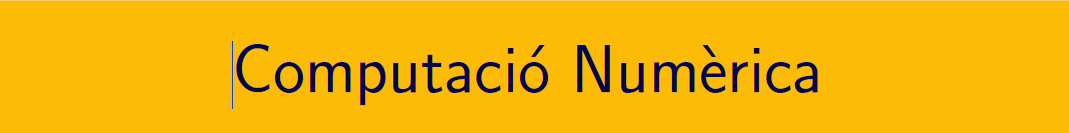

================================================================================

# Pràctica 12. Equacions diferencials ordinàries (I).

`Document preparat per M. Àngela Grau Gotés - 17 de maig de 2023`

## APRENEM... 

## **PVI  **$y^{\prime}=t\sqrt{y},\quad y(1)=4,\quad 1\leq t\leq 2\,.$

### MATLAB® - Solució analítica 

Consulteu l'ajuda de la comanda [DSOLVE](https://es.mathworks.com/help/symbolic/dsolve.html)

format longG
syms y(t)
eqn = diff(y,t) == t*y;
cond = y(1) == 4;
ySol(t) = dsolve(eqn,cond) 

$$ySol(t) = 4\,{\mathrm{e}}^{-\frac{1}{2}}\,{\mathrm{e}}^{\frac{t^{2}}{2}}$$

ySol2(t)=0.0625*(7+t^2)^2

$$ySol2(t) = \frac{{\left(t^{2}+7\right)}^{2}}{16}$$

La solució es pot respresentar a l'interval [1,2]

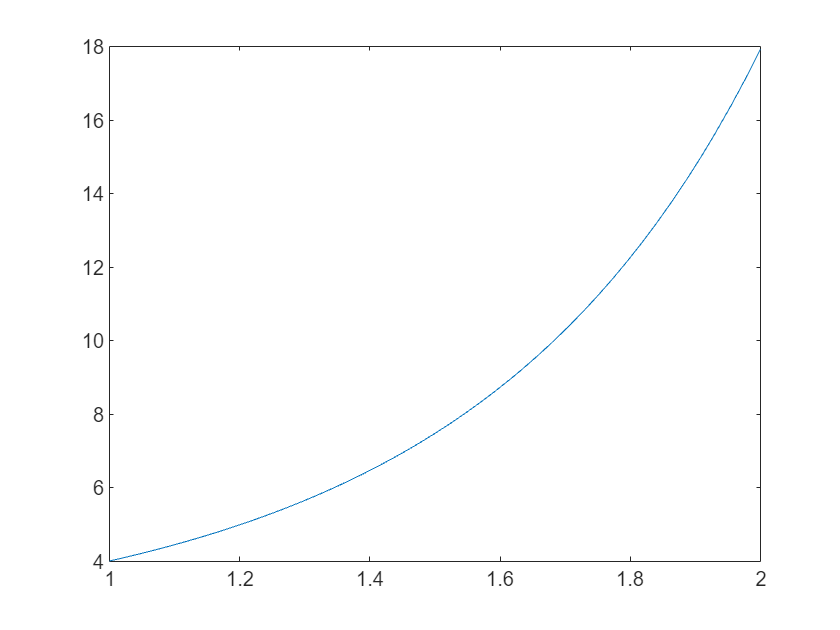

fplot(ySol,[1,2])

**Isoclines del camp de direccions y'=f(t,y)**

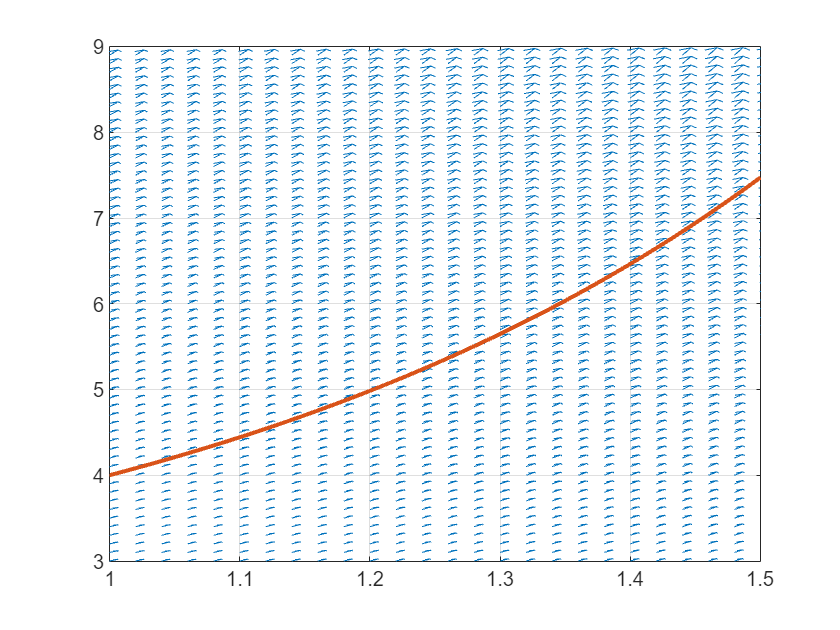

t=1:0.02:1.5; 
y=3:0.1:9;
[TT,YY] = meshgrid(t,y);
DT = ones(size(TT));
f = @(t,y)t.*(y);
DY = f(TT,YY);
% Gràfic
figure(1)
quiver(TT,YY,DT,DY);grid,axis([1,1.5,3,9]), hold on
fplot(ySol,[1,2],'LineWidth',2), hold off

ySolFunc = matlabFunction(ySol);

### Solucions aproximades numèricament

#### `Mètode d'Euler per h = 0.2, h = 0.1 ....`

a = 1; alpha = 4;    % y(a) = alpha
b = 2;               % y(b) = ...
h = 0.1;
[ Y1, t1 ] = Euler( f,a,b,h,alpha );
h = 0.2;
[ Y2, t2 ] = Euler( f,a,b,h,alpha );
disp(array2table([t1;Y1]','VariableNames',{'t_k','Y_k'}))

    t_k          Y_k       
    ___    ________________
      1                   4
    1.1                 4.4
    1.2               4.884
    1.3             5.47008
    1.4           6.1811904
    1.5         7.046557056
    1.6        8.1035406144
    1.7      9.400107112704
    1.8    10.9981253218637
    1.9    12.9777878797991
      2     15.443567576961


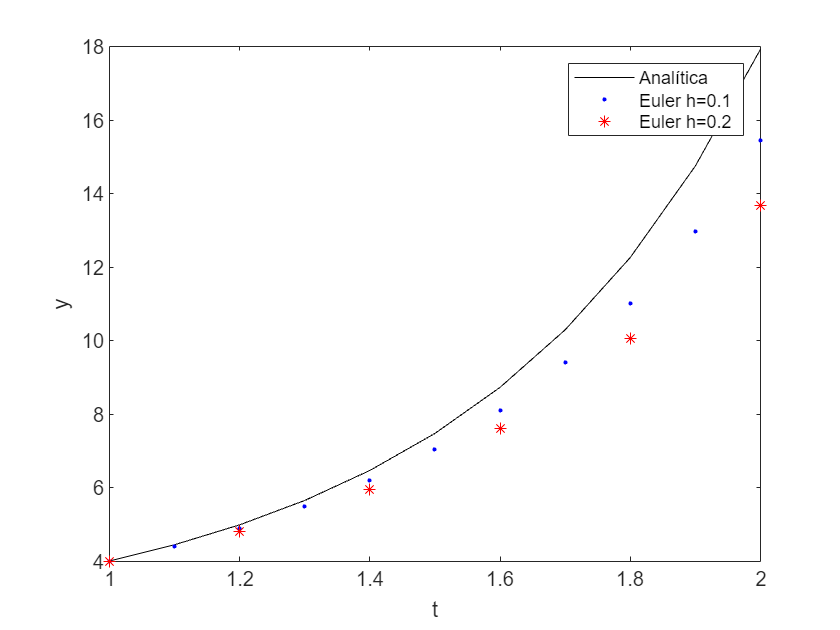

plot(t, ySolFunc(t), 'k', t1, Y1, 'b.', t2, Y2, 'r*');
legend('Analítica', 'Euler h=0.1', 'Euler h=0.2');
xlabel('t');
ylabel('y');

errorlocal =  double(abs(ySol2(t1)-Y1))

errorlocal =                          0                0.18724375                    0.4319                0.75032375                 1.1635904               1.698900806              2.3914406144            3.286850862704          4.44452532186368          5.94203162979914          7.88106757696098


errorGlobal =  sum(errorlocal)

errorGlobal =           28.1778747117278

#### `Mètode d'Euler modificat`

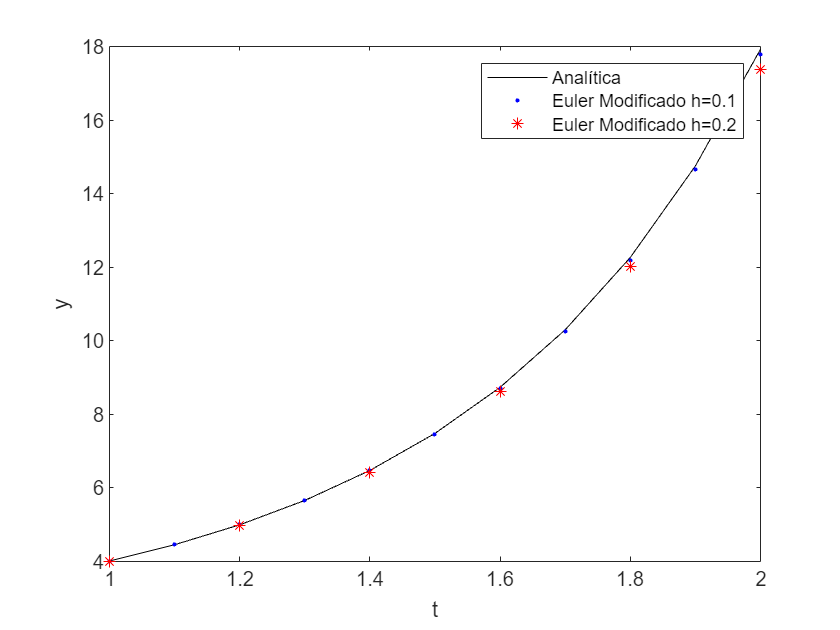

a = 1; alpha = 4;      % y(a) = alpha
b = 2;               % y(b) = ...
h = 0.1;

t = a:h:b;
t2 = a:0.2:b;
[ YM1 ] = EulerMod( f,a,b,h,alpha );
h = 0.2;
[ YM2 ] = EulerMod( f,a,b,h,alpha );
plot(t, ySolFunc(t), 'k', t, YM1, 'b.', t2, YM2, 'r*');
legend('Analítica', 'Euler Modificado h=0.1', 'Euler Modificado h=0.2');
xlabel('t');
ylabel('y');

#### `Mètode de Heun`

a = 1; alpha = 4;      % y(a) = alpha
b = 1.5;               % y(b) = ...

% [ YH1 ] = Heun( f,a,b,h,alpha );

#### `Mètode RK4`

a = 1; alpha = 4;      % y(a) = alpha
b = 1.5;               % y(b) = ...



% [ YK1 ] = RK4( f,a,b,h,alpha );

#### `Solvers de MATLAB®: ode23, ode45`




% Plot solution
% plot(t1,y1,t2,y2)
% xlabel('t')
% ylabel('solution y')
% title('$y^{\prime}(t)=t\sqrt{y(t)}$','Interpreter¡','latex')

## PRACTIQUEM... 

### Exercici 1. 

 Resoleu els exercicis: 2,3,4,5,6,7, 8 i 11 del document practica12_edos_I.pdf disponible en el campus virtual.

#### **a) PVI  **$y^{\prime}(t)=-y(t)+t+1\,,\quad y(0)=1,\quad 0\leq t\leq 1\,.$

%% Respostes document --->  prac12_16maig_metodes_exercici_a.html   

#### **b) PVI  **$y^{\prime}(t)=te^{3t}-2y(t)\,,\quad y(0)=0,\quad 0\leq t\leq 1\,.$  

%% Respostes document --->  prac12_16maig_metodes_exercici_b.html   

#### **c) PVI  **$y^{\prime}(t)=\cos(2t)+\sin(3t)\,,\quad y(0)=1,\quad 0\leq t\leq 1\,.$

%% Respostes document --->  prac12_16maig_metodes_exercici_c.html   

### Exercici 2. 

Resoleu l'exercici 10 i 11 del document practica12_edos_I.pdf disponible en el campus virtual.

%% Respostes document --->  prac12_16maig_metodes_exercici_2.html   

function [ w,t ] = Euler(f,a,b,h,alpha)
% Mètode d'Euler
t=[a:h:b];
N=length(t);
w(1)=alpha;
for i=1:N-1
    w(i+1)=w(i)+h*f(t(i),w(i));
end
end
%-----------------------------------------
function  w  = EulerMod( f,a,b,h,alpha )
t=[a:h:b];
N=length(t);
w(1)=alpha;
for i=1:N-1
    k1 = w(i) + (h/2)*f(t(i),w(i));
    w(i+1)=w(i)+h*f(t(i)+ h/2,k1);
end
end
%-----------------------------------------
function  w  = EulerMill( f,a,b,h,alpha )
% Mètode d'Euler Millorat o HEUN

end
%----------------------------------------
function  w  = RK4( f,a,b,h,alpha )
% Mètode RK4

end